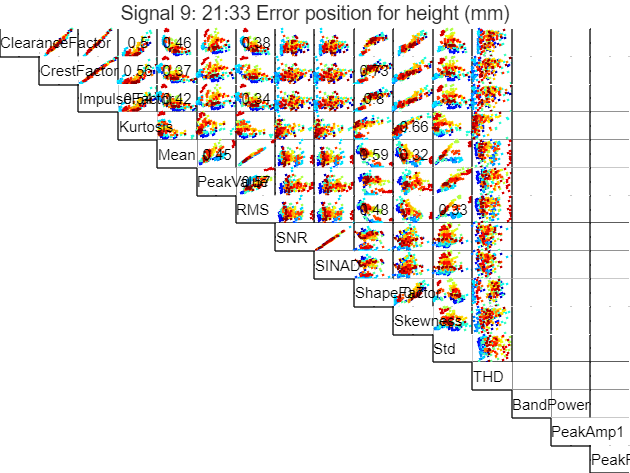

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedSignal = 9; % 21:33 Error position for height (mm)
saveFigures = false;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00  0.97  0.99  0.50  0.46  0.00  0.38  0.02  0.02  0.83  0.84  0.01   NaN   NaN   NaN   NaN
0.00  0.00  0.99  0.56  0.37  0.01  0.29  0.02  0.02  0.73  0.82  0.02   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.54  0.42  0.00  0.34  0.02  0.02  0.80  0.84  0.01   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.09  0.02  0.08  0.01  0.00  0.21  0.66  0.00   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.45  0.98  0.00  0.00  0.59  0.32  0.22   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.57  0.01  0.01  0.02  0.00  0.81   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.48  0.26  0.33   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.02  0.03  0.02   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02  0.03  0.02   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.70  0.01   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

combination = 1;
selectedFeature = 3;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 7 = 0.98
     3     4     5     7    10

     3     4     5    10



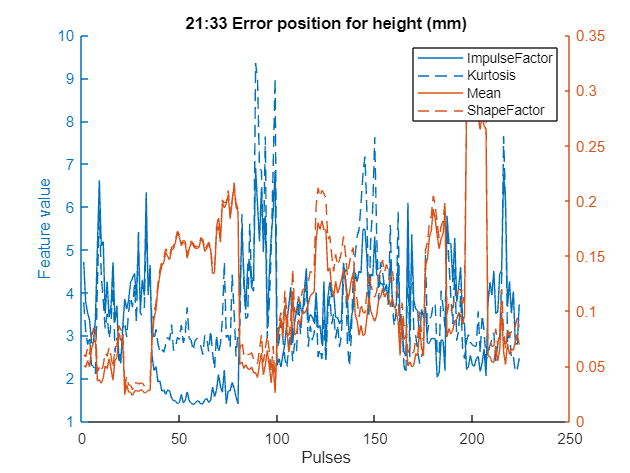

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [3 4];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

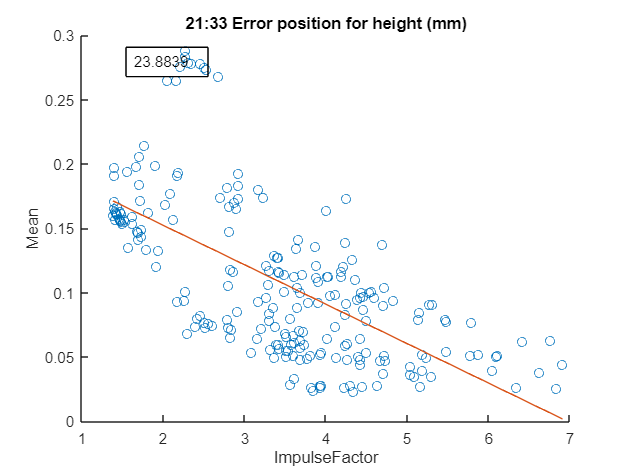

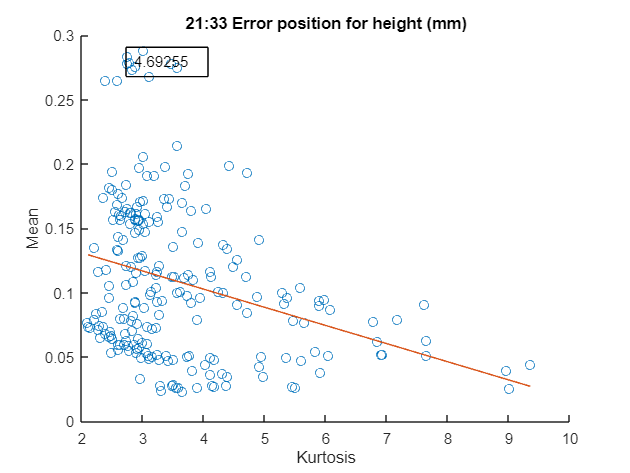

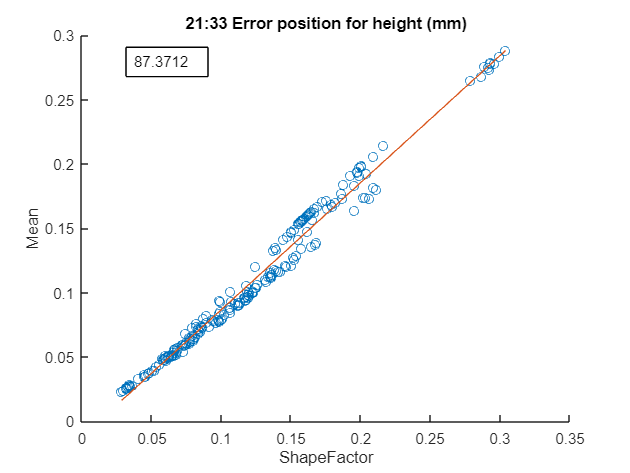

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

1 2 3

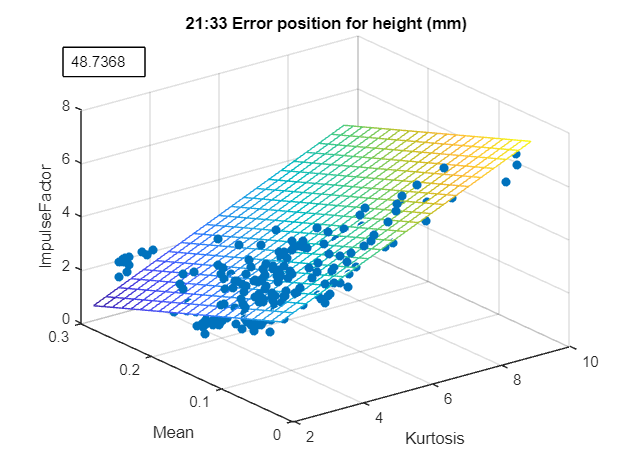

1 2 4

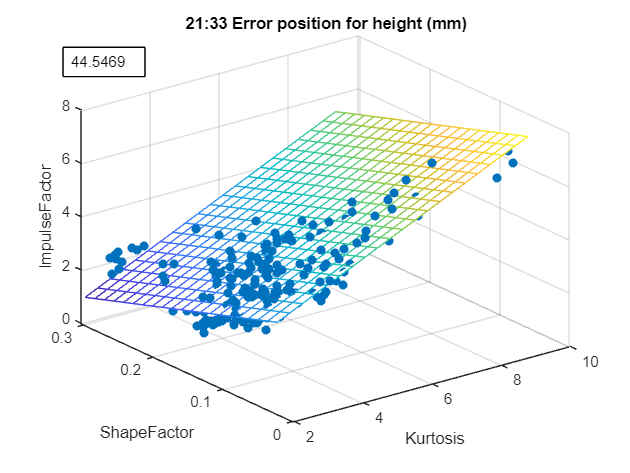

1 3 4

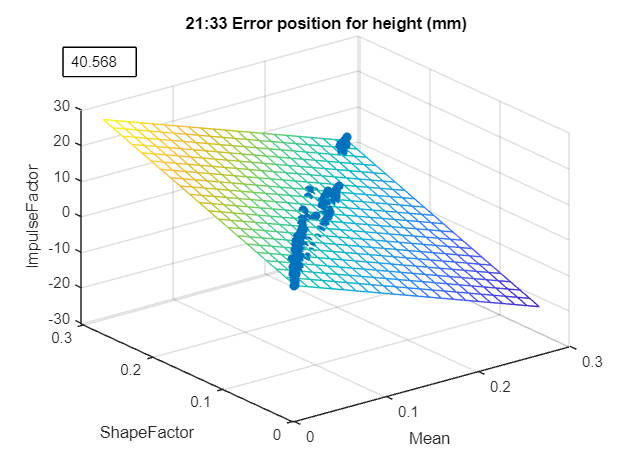

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 2

combination = 2;
selectedFeature = 4;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 1 Sig 2 = 0.97
Sig 1 Sig 3 = 0.99
     1     2     3     4    11

     1     4    11



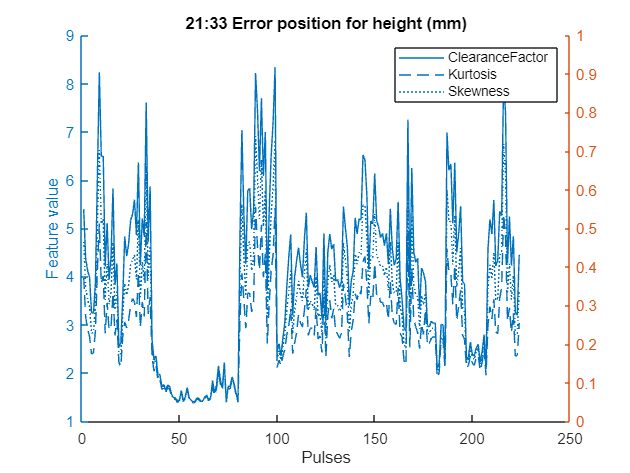

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

xx = 1:numOfPulses;
plotyyy(xx', selectedFeatureData{1}, xx', selectedFeatureData{2}, xx', selectedFeatureData{3}, leg);

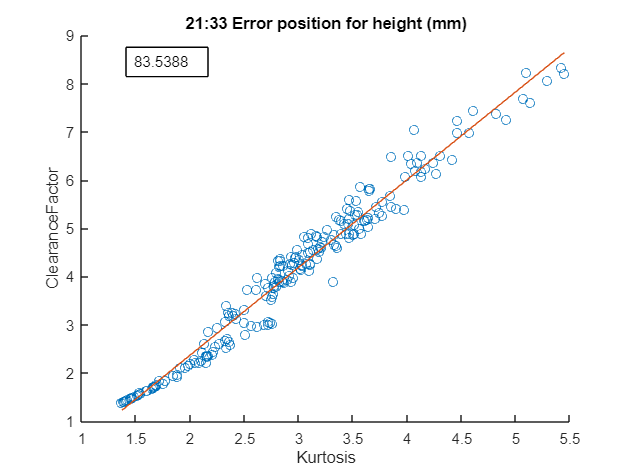

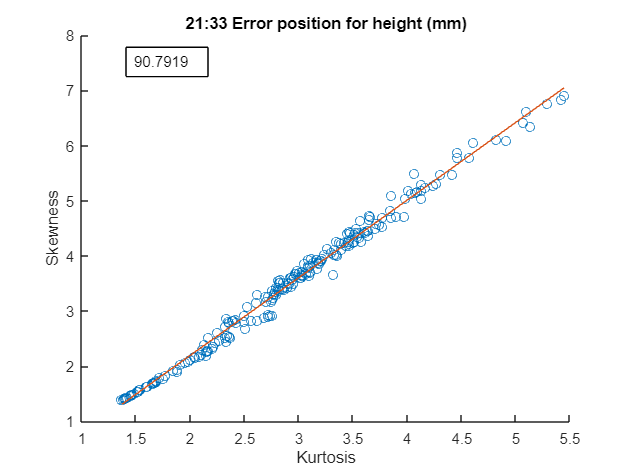

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 3

combination = 3;
selectedFeature = 5;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [4 5];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 4

combination = 4;
selectedFeature = 7;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [3 4 5];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 5

combination = 5;
selectedFeature = 10;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [3 4];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 6

combination = 6;
selectedFeature = 11;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2 3];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 7

combination = 7;
selectedFeature = 12;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    else
        yyaxis left
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature + "Combo" + combination;
    print(filename,'-depsc','-tiff')
end

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
    end
end

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end